AAE 334 HW6 MATLAB CODE 

clear all; close all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Spring\AAE334\MATLAB\outputs\HW6';
set(groot, 'defaulttextinterpreter',"latex");
set(groot, 'defaultAxesTickLabelInterpreter',"latex");
set(groot, 'defaultLegendInterpreter',"latex");

### 1 - setup

% Define plane dimensions 
b = inch2m(36*12+1);  % [m]
c_r = inch2m(66);  % [m]
b_cs = inch2m(16*12+9);  % [m]
b_os = b - b_cs;  % [m]
c_tip = inch2m(4*12);  % [m]
u_a = knots2m_s(124);  % [m/s]
W = lbf2newtons(2550);  % [N]
m = W/9.81

m = 1.1563e+03

h_alt = inch2m(8500*12);  % [m]
gamma = 1.4;
R = 287.95; 
% Obtaining the atmospheric conditions at the given altitude 
[rho_alt,a_alt,T_alt,P_alt,nu_alt,h,sigma] = atmos(h_alt,'units','SI');
% Calculating the viscosity at the given altitude using Sutherland's
% formula
myu = sutherland_visc_calc(T_alt,"air")

myu = 1.7048e-05

nu = myu/rho_alt

nu = 1.7982e-05

% Reynolds number range
Re_range1 = 1.0:0.5:7.5;
Re_legendCell = cellstr(num2str(Re_range1', 'Re=%-f'));

### 1 - a

% wing area
S1 = c_r*b_cs;
S2 = (c_r + c_tip)*b_os;
S = S1 + S2;
% wing aspect ratio
AR = b^2/S;
% mach number
Ma = u_a/sqrt(gamma*R*T_alt);
% lift coefficient
C_L = calc_lift_coeff(W,rho_alt,u_a,S);
% Reynolds number for the wing root section 
Re_root = calc_reynolds_number(rho_alt,u_a,c_r,myu);
% Reynolds number for the wing tip section 
Re_tip = calc_reynolds_number(rho_alt,u_a,c_tip,myu);

### 1 - b

% Loading data
cl_alpha_1b = readmatrix('inputs\hw6\1b_cl_alpha.csv');
cd_alpha_1b = readmatrix('inputs\hw6\1b_cd_alpha.csv');
clcd_alpha_1b = readmatrix("inputs\hw6\1b_clcd_alpha.csv");

[alpha1_b1, cl_b1] = read_batch_analysis_data(cl_alpha_1b);
[alpha2_b1, cd_b1] = read_batch_analysis_data(cd_alpha_1b);
[alpha3_b1, clcd_b1] = read_batch_analysis_data(clcd_alpha_1b);

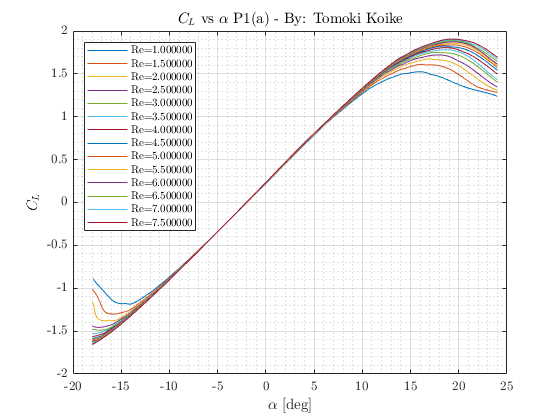

% Plotting 
% cl coeffs
fig1 = figure('Renderer',"painters");
    hold on 
    plot_array(alpha1_b1,cl_b1)
    hold off
    title('$C_L$ vs $\alpha$ P1(a) - By: Tomoki Koike')
    xlabel('$\alpha$ [deg]')
    ylabel('$C_L$')
    legend(Re_legendCell, "Location","northwest","FontSize",8)
    grid on; grid minor; box on;
saveas(fig1, fullfile(fdir, 'Cl_vs_alpha_1b.png'));

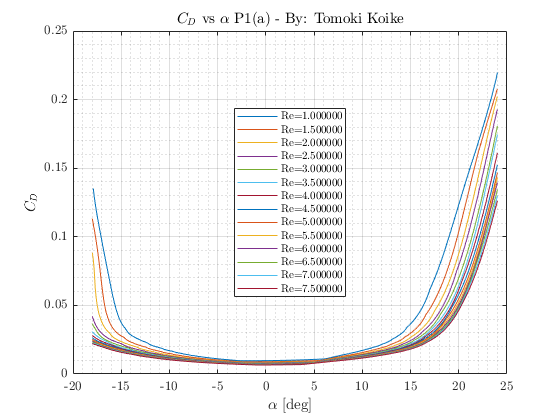

% cd coeffs
fig2 = figure('Renderer',"painters");
    hold on 
    plot_array(alpha2_b1,cd_b1)
    hold off
    title('$C_D$ vs $\alpha$ P1(a) - By: Tomoki Koike')
    xlabel('$\alpha$ [deg]')
    ylabel('$C_D$')
    legend(Re_legendCell, "Location","best","FontSize",8)
    grid on; grid minor; box on;
saveas(fig2, fullfile(fdir, 'Cd_vs_alpha_1b.png'));

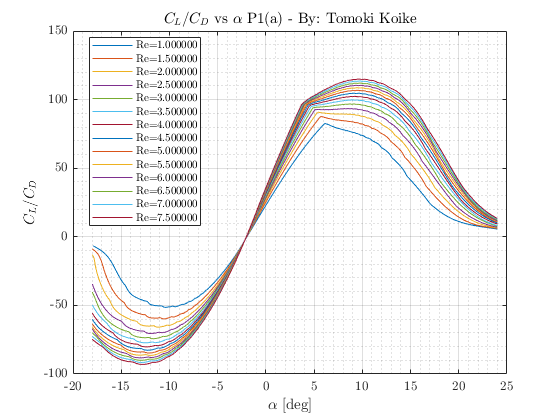

% cd coeffs
fig3 = figure('Renderer',"painters");
    hold on 
    plot_array(alpha3_b1,clcd_b1)
    hold off
    title('$C_L$/$C_D$ vs $\alpha$ P1(a) - By: Tomoki Koike')
    xlabel('$\alpha$ [deg]')
    ylabel('$C_L$/$C_D$')
    legend(Re_legendCell, "Location","best","FontSize",8)
    grid on; grid minor; box on;
saveas(fig3, fullfile(fdir, 'ClCd_vs_alpha_1b.png'));

% Computations
max_clcd_b1 = max(max(clcd_b1));

### 1 - d

% Loading data
cl_alpha_1d = readmatrix('inputs\hw6\1d_cl_alpha.csv');
cl_cd_1d = readmatrix('inputs\hw6\1d_cl_cd.csv');
clcd_alpha_1d = readmatrix("inputs\hw6\1d_clcd_alpha.csv");
alpha1_1d = cl_alpha_1d(:,1);
cl1_1d = cl_alpha_1d(:,2);
cd_1d = cl_cd_1d(:,1);
cl2_1d = cl_cd_1d(:,2);
alpha2_1d = clcd_alpha_1d(:,1);
clcd_1d = clcd_alpha_1d(:,2);

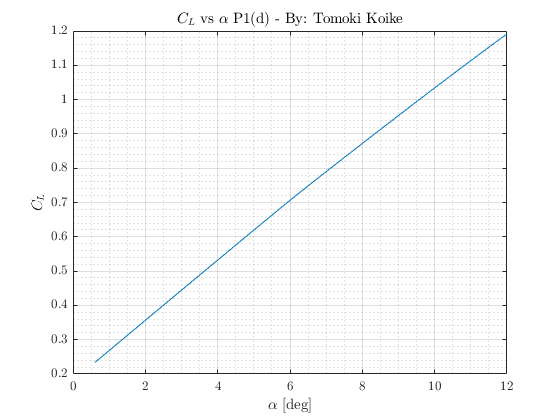

% Plotting 
fig4 = figure("Renderer","painters");
    plot(alpha1_1d, cl1_1d)
    title('$C_L$ vs $\alpha$ P1(d) - By: Tomoki Koike')
    xlabel('$\alpha$ [deg]')
    ylabel('$C_L$')
    grid on; grid minor; box on
saveas(fig4, fullfile(fdir, 'cl_alpha_1d.png'));

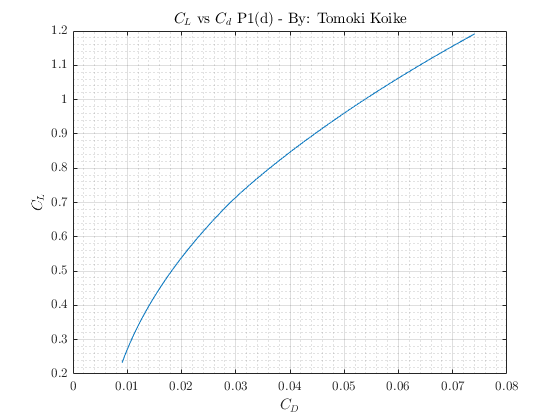

fig5 = figure("Renderer","painters");
    plot(cd_1d, cl2_1d)
    title('$C_L$ vs $C_d$ P1(d) - By: Tomoki Koike')
    xlabel('$C_D$')
    ylabel('$C_L$')
    grid on; grid minor; box on
saveas(fig5, fullfile(fdir, 'cl_cd_1d.png'));

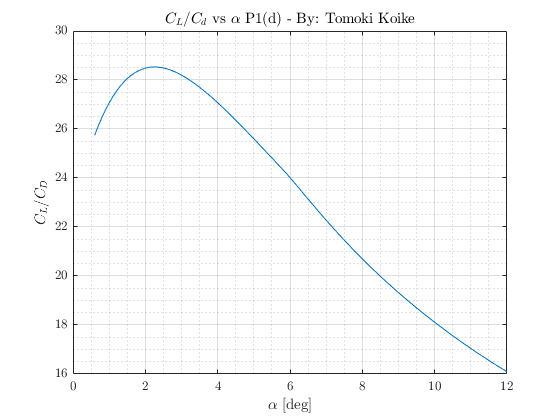

fig6 = figure("Renderer","painters");
    plot(alpha2_1d, clcd_1d)
    title('$C_L$/$C_d$ vs $\alpha$ P1(d) - By: Tomoki Koike')
    xlabel('$\alpha$ [deg]')
    ylabel('$C_L$/$C_D$')
    grid on; grid minor; box on
saveas(fig6, fullfile(fdir, 'clcd_alpha_1d.png'));

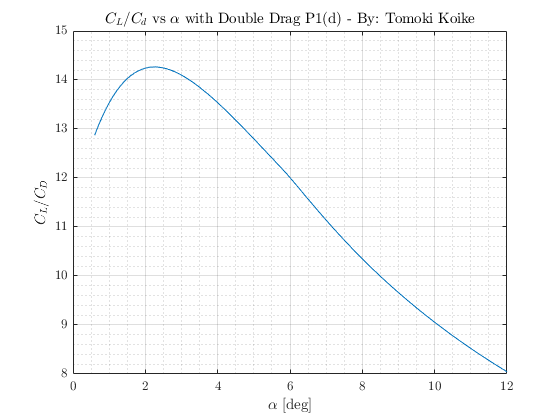

% Computations 
max_clcd_1d = max(clcd_1d);
clcd_pdiff_1b_1d = max_clcd_b1 - max_clcd_1d;

% Double the drag coefficient to be more realistic
clcd_1d_real = cl1_1d./(2*cd_1d);
fig7 = figure("Renderer","painters");
    plot(alpha2_1d, clcd_1d_real)
    title('$C_L$/$C_d$ vs $\alpha$ with Double Drag P1(d) - By: Tomoki Koike')
    xlabel('$\alpha$ [deg]')
    ylabel('$C_L$/$C_D$')
    grid on; grid minor; box on
saveas(fig7, fullfile(fdir, 'clcd_alpha_1d_real.png'));


[max_clcd_1d_real, idx] = max(clcd_1d_real)

max_clcd_1d_real = 14.2671

idx = 18

max_alpha_1d = alpha1_1d(idx)

max_alpha_1d = 2.3000

cl_at_max_alpha = cl1_1d(idx)

cl_at_max_alpha = 0.3830

slope_1d = (cl1_1d(idx+1)-cl1_1d(idx-1))/deg2rad(alpha1_1d(idx+1)-alpha1_1d(idx-1))

slope_1d = 5.0376

th_slope_1d = 6.588/(1 + 6.588/pi/AR)

th_slope_1d = 4.5617

pdiff = (slope_1d - th_slope_1d) / th_slope_1d * 100 

pdiff = 10.4325

### 1 - e

% Creating table
data_array = [2.30 0.01342 0.00714 0.00629 -0.03504 0.38296; 10.00 0.05710 0.0108 0.04627 -0.00386 1.03421];
data_T = array2table(data_array, "VariableNames",{'Alpha', 'CD', 'VCD', 'ICD', 'Cm', 'CL'});


% e factor 
e = (data_T.CL).^2/pi/AR./data_T.CD

e =     0.7368
    1.2630


data_T = addvars(data_T, e, 'after', "CL")

data_T = 2×7 table
    Alpha      CD         VCD        ICD         Cm         CL          e   
    _____    _______    _______    _______    ________    _______    _______

     2.3     0.01342    0.00714    0.00629    -0.03504    0.38296    0.73684
      10      0.0571     0.0108    0.04627    -0.00386     1.0342      1.263


% total drag and induced drag ratio
Dtot_Di_ratio = data_T.ICD./data_T.CD

Dtot_Di_ratio =     0.4687
    0.8103



% Calculate the drag
Vinf = [62.652; 38.125];
D = 0.5 * rho_alt * u_a^2 .* data_T.CD * S;
data_T = addvars(data_T, D, 'after', 'e')

data_T = 2×8 table
    Alpha      CD         VCD        ICD         Cm         CL          e         D   
    _____    _______    _______    _______    ________    _______    _______    ______

     2.3     0.01342    0.00714    0.00629    -0.03504    0.38296    0.73684    663.26
      10      0.0571     0.0108    0.04627    -0.00386     1.0342      1.263    2822.1


data_T = addvars(data_T, Vinf, 'before', 'D')

data_T = 2×9 table
    Alpha      CD         VCD        ICD         Cm         CL          e        Vinf       D   
    _____    _______    _______    _______    ________    _______    _______    ______    ______

     2.3     0.01342    0.00714    0.00629    -0.03504    0.38296    0.73684    62.652    663.26
      10      0.0571     0.0108    0.04627    -0.00386     1.0342      1.263    38.125    2822.1



bourget = data_T.CL./data_T.CD.*data_T.Vinf

bourget = 	1.0e+03 *

    1.7879
    0.6905


### 1 - f

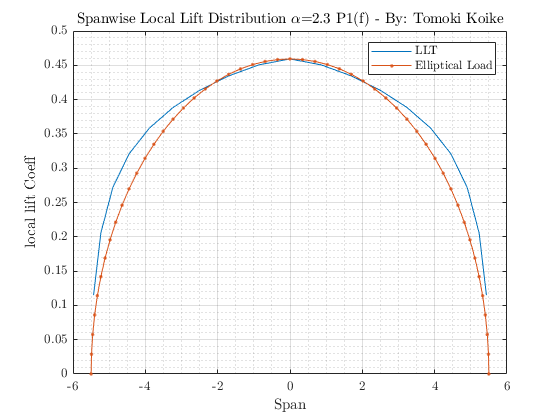

data_1f = readmatrix("inputs\hw6\1f_lcl_lift.csv");
b_llt = data_1f(:,1);
llt = data_1f(:,2);
b_e_1f = data_1f(:,3);
llt_e_1f = data_1f(:,4);

% Plotting
fig8 = figure("Renderer","painters");
    plot(b_llt, llt)
    title('Spanwise Local Lift Distribution $\alpha$=2.3 P1(f) - By: Tomoki Koike')
    xlabel('Span')
    ylabel('local lift Coeff')
    hold on 
    plot(b_e_1f, llt_e_1f, '.-')
    hold off
    legend('LLT', 'Elliptical Load')
    grid on; grid minor; box on
saveas(fig8, fullfile(fdir, 'llt_elliptical.png'));

### 1 - g

% Calculate the area under LLT
Ltot_1g = trapz(rmmissing(b_llt), rmmissing(llt))

Ltot_1g = 4.1522

Ltot_1g = Ltot_1g * 0.5 * rho_alt * u_a^2 * S;
X_CP = 0.593;
M_LE = X_CP*Ltot_1g/b

M_LE = 1.1065e+04

d = inch2m(15*12+6) - X_CP

d = 4.1314

L_tail = M_LE / d

L_tail = 2.6782e+03

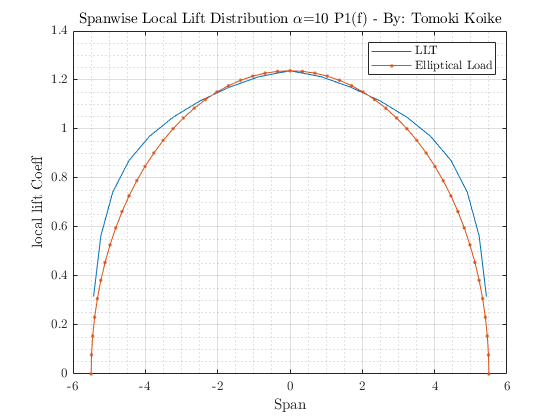


data_1f2 = readmatrix("inputs\hw6\1f_lcl_lift10.csv");
b_llt2 = data_1f2(:,1);
llt2 = data_1f2(:,2);
b_e_1f2 = data_1f2(:,3);
llt_e_1f2 = data_1f2(:,4);

% Plotting
fig9 = figure("Renderer","painters");
    plot(b_llt2, llt2)
    title('Spanwise Local Lift Distribution $\alpha$=10 P1(f) - By: Tomoki Koike')
    xlabel('Span')
    ylabel('local lift Coeff')
    hold on 
    plot(b_e_1f2, llt_e_1f2, '.-')
    hold off
    legend('LLT', 'Elliptical Load')
    grid on; grid minor; box on
saveas(fig9, fullfile(fdir, 'llt_elliptical10.png'));


% Calculate the area under LLT
Ltot_1g2 = trapz(rmmissing(b_llt2), rmmissing(llt2))

Ltot_1g2 = 11.2129

Ltot_1g2 = Ltot_1g2 * 0.5 * rho_alt * u_a^2 * S;
X_CP2 = 0.456;
M_LE2 = X_CP2*Ltot_1g2/b;
d2 = inch2m(15*12+6) - X_CP2;
L_tail = M_LE2 / d2

L_tail = 5.3830e+03

### 2

ICD2 = 0.00627;
CL2 = 0.38615;
e = CL2^2/pi/ICD2/AR

e = 1.6035

ICDrat = 0.00627/0.01341 

ICDrat = 0.4676

data2 = readmatrix("inputs\hw6\CL3.csv");
alpha2 = rmmissing(data2(:,1));
cl2 = rmmissing(data2(:,2));
alpha_interp = interp1(cl2, alpha2, 0.3830);

data21 = readmatrix("inputs\hw6\ICD2.csv");
data22 = readmatrix("inputs\hw6\CD2.csv");
a21 = rmmissing(data21(:,1));
ICD21 = rmmissing(data21(:,2));
a22 = rmmissing(data22(:,1));
CD22 = rmmissing(data22(:,2));

ICD_interp = interp1(a21, ICD21, alpha_interp)

ICD_interp = 0.0076

CD_interp = interp1(a22, CD22, alpha_interp)

CD_interp = 0.0148

ratio_interp = ICD_interp/CD_interp

ratio_interp = 0.5121

### 3

ICD3 = 0.00682;
CL3 = 0.40511;
e = CL3^2/pi/ICD3/AR

e = 1.6225

ICDrat3 = 0.00627/0.01341 

ICDrat3 = 0.4676

data3 = readmatrix("inputs\hw6\CL3.csv");
alpha3 = rmmissing(data3(:,1));
cl3 = rmmissing(data3(:,2));
alpha_interp3 = interp1(cl3, alpha3, 0.3830)

alpha_interp3 = 2.7271


data31 = readmatrix("inputs\hw6\ICD3.csv");
data32 = readmatrix("inputs\hw6\CD3.csv");
a31 = rmmissing(data31(:,1));
ICD31 = rmmissing(data31(:,2));
a32 = rmmissing(data32(:,1));
CD32 = rmmissing(data32(:,2));

ICD_interp3 = interp1(a31, ICD31, alpha_interp3)

ICD_interp3 = 0.0061

CD_interp3 = interp1(a32, CD32, alpha_interp3)

CD_interp3 = 0.0133

ratio_interp3 = ICD_interp3/CD_interp3

ratio_interp3 = 0.4603

### FUNCTIONS 

function C_L = calc_lift_coeff(L,rho,v,S)
    C_L = 2*L/rho/v^2/S;
end

function Re = calc_reynolds_number(rho, v, c, myu)
    Re = rho * v * c / myu;
end

function [t, y] = read_batch_analysis_data(data)
    t = [];
    y = [];
    ct = 1;
    for i = 1:3:40
        t(:,ct) = data(:,i);
        y(:,ct) = data(:,i+1);
        ct = ct + 1;
    end
end

function plot_array(t_array, y_array)
    for i = 1:size(t_array, 2)
        plot(t_array(:,i), y_array(:,i), '-')
    end
end